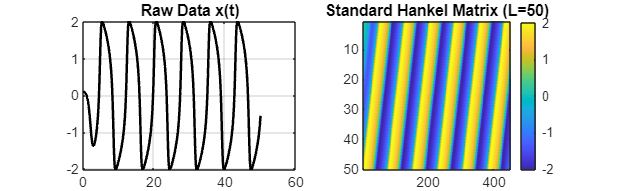

%% EXP 1A: VAN DER POL - STANDARD HANKEL DMD

clear; clc; close all;

% 1. GENERATE DATA
mu = 2.0; 
vdp = @(t, y) [y(2); mu*(1-y(1)^2)*y(2) - y(1)];
dt = 0.1; t_span = 0:dt:50;        
[t, states] = ode45(vdp, t_span, [0.1; 0]);
raw_x = states(:, 1)'; 

% 2. HANKELIZATION
L = 50; N = length(raw_x); K = N - L + 1;
H = zeros(L, K);
for k = 1:K, H(:, k) = raw_x(k : k+L-1); end

% VISUALIZE DATA PIPELINE
figure('Name', 'Pipeline 1A', 'Color', 'w', 'Position', [100, 500, 1000, 300]);
subplot(1,2,1); plot(t, raw_x, 'k', 'LineWidth', 1.5); title('Raw Data x(t)'); grid on;
subplot(1,2,2); imagesc(H); colormap(parula); title('Standard Hankel Matrix (L=50)'); colorbar;


% 3. SPLIT & SVD
train_cols = floor(K * 0.6);
H_train = H(:, 1:train_cols); H_test = H(:, train_cols+1:end);
X = H_train(:, 1:end-1); X_prime = H_train(:, 2:end);

r = 15; % Rank
[U, S, V] = svd(X, 'econ');
Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

% 4. DMD OPERATOR & FORECAST
A_tilde = (Ur') * X_prime * Vr * inv(Sr);
[W, D] = eig(A_tilde); lambdas = diag(D);
Phi = X_prime * Vr * inv(Sr) * W;
b = pinv(Phi) * X(:, 1);        

total_snapshots = K; time_dynamics = zeros(r, total_snapshots);
for step = 0:total_snapshots-1, time_dynamics(:, step+1) = (b .* (lambdas .^ step)); end
H_forecast = real(Phi * time_dynamics);
signal_forecast = H_forecast(1, :); 

% 5. METRICS
actual = H(1, train_cols+1:end); predicted = signal_forecast(train_cols+1:end);
err_vec = abs(actual - predicted);
rmse = sqrt(mean(err_vec.^2)); mae = mean(err_vec);
thresh = 0.1 * std(raw_x); div_idx = find(err_vec > thresh, 1);
if isempty(div_idx), vpt = 'Full Window'; else, vpt = [num2str(div_idx*dt, '%.2f'), 's']; end

disp('--- EXP 1A: STANDARD VAN DER POL ---');

--- EXP 1A: STANDARD VAN DER POL ---


disp(['RMSE: ', num2str(rmse, '%.4f'), ' | MAE: ', num2str(mae, '%.4f'), ' | VPT: ', vpt]);

RMSE: 0.1386 | MAE: 0.1092 | VPT: 0.80s


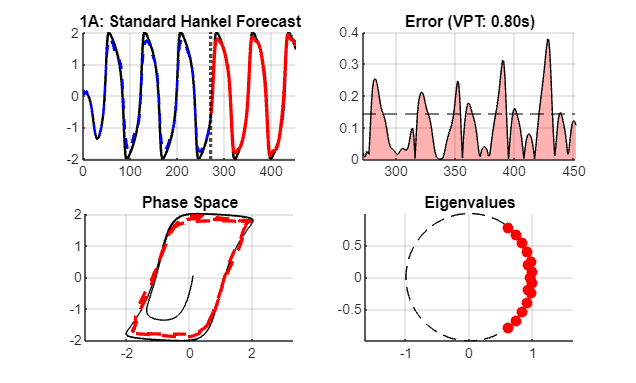


% 6. DASHBOARD
figure('Name', 'Dashboard 1A', 'Color', 'w', 'Position', [150, 50, 1000, 600]);
subplot(2,2,1); hold on; plot(1:K, H(1,:), 'k-', 'LineWidth', 1.5); 
plot(1:train_cols, signal_forecast(1:train_cols), 'b--', 'LineWidth', 1.5);
plot(train_cols+1:K, predicted, 'r-', 'LineWidth', 2); xline(train_cols, 'k:', 'LineWidth', 2);
title('1A: Standard Hankel Forecast'); grid on;

subplot(2,2,2); hold on; area(train_cols+1:K, err_vec, 'FaceColor', 'r', 'FaceAlpha', 0.3);
yline(thresh, 'k--'); title(['Error (VPT: ', vpt, ')']); grid on;

subplot(2,2,3); hold on; d=8; plot(H(1,1:end-d), H(1,1+d:end), 'k-');
plot(signal_forecast(train_cols+1:end-d), signal_forecast(train_cols+1+d:end), 'r--', 'LineWidth', 2);
title('Phase Space'); grid on; axis equal;

subplot(2,2,4); hold on; th=linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerFaceColor', 'r'); title('Eigenvalues'); grid on; axis equal;

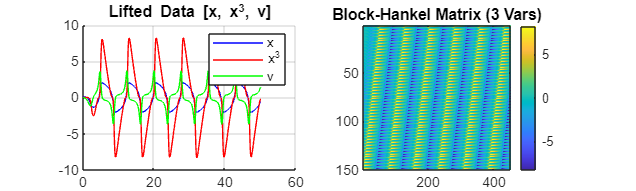


% EXP 1B: VAN DER POL - HYBRID KOOPMAN (UPLIFTED)

clear; clc; close all;

% 1. GENERATE DATA
mu = 2.0; 
vdp = @(t, y) [y(2); mu*(1-y(1)^2)*y(2) - y(1)];
dt = 0.1; t_span = 0:dt:50;        
[t, states] = ode45(vdp, t_span, [0.1; 0]);
raw_x = states(:, 1)'; 

% 2. KOOPMAN LIFTING & HANKELIZATION
vel_x = gradient(raw_x) / dt;
Lifted = [raw_x; raw_x.^3; vel_x]; % Dictionary: x, x^3, dx/dt
L = 50; num_vars = 3; N = length(raw_x); K = N - L + 1;
H = zeros(num_vars * L, K);
for k = 1:K, window = Lifted(:, k:k+L-1); H(:, k) = window(:); end

% VISUALIZE DATA
figure('Name', 'Pipeline 1B', 'Color', 'w', 'Position', [100, 500, 1000, 300]);
subplot(1,2,1); hold on; plot(t, raw_x, 'b', t, raw_x.^3, 'r', t, vel_x, 'g'); 
title('Lifted Data [x, x^3, v]'); legend('x', 'x^3', 'v'); grid on;
subplot(1,2,2); imagesc(H); colormap(parula); title('Block-Hankel Matrix (3 Vars)'); colorbar;


% 3. SPLIT & SVD
train_cols = floor(K * 0.6);
H_train = H(:, 1:train_cols); H_test = H(:, train_cols+1:end);
X = H_train(:, 1:end-1); X_prime = H_train(:, 2:end);

r = 15; % Rank
[U, S, V] = svd(X, 'econ');
Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

% 4. DMD OPERATOR & FORECAST
A_tilde = (Ur') * X_prime * Vr * inv(Sr);
[W, D] = eig(A_tilde); lambdas = diag(D);
Phi = X_prime * Vr * inv(Sr) * W;
b = pinv(Phi) * X(:, 1);        

total_snapshots = K; time_dynamics = zeros(r, total_snapshots);
for step = 0:total_snapshots-1, time_dynamics(:, step+1) = (b .* (lambdas .^ step)); end
H_forecast = real(Phi * time_dynamics);
signal_forecast = H_forecast(1, :); 

% 5. METRICS
actual = H(1, train_cols+1:end); predicted = signal_forecast(train_cols+1:end);
err_vec = abs(actual - predicted);
rmse = sqrt(mean(err_vec.^2)); mae = mean(err_vec);
thresh = 0.1 * std(raw_x); div_idx = find(err_vec > thresh, 1);
if isempty(div_idx), vpt = 'Full Window'; else, vpt = [num2str(div_idx*dt, '%.2f'), 's']; end

disp('--- EXP 1B: HYBRID VAN DER POL ---');

--- EXP 1B: HYBRID VAN DER POL ---


disp(['RMSE: ', num2str(rmse, '%.4f'), ' | MAE: ', num2str(mae, '%.4f'), ' | VPT: ', vpt]);

RMSE: 0.2268 | MAE: 0.1963 | VPT: 0.70s


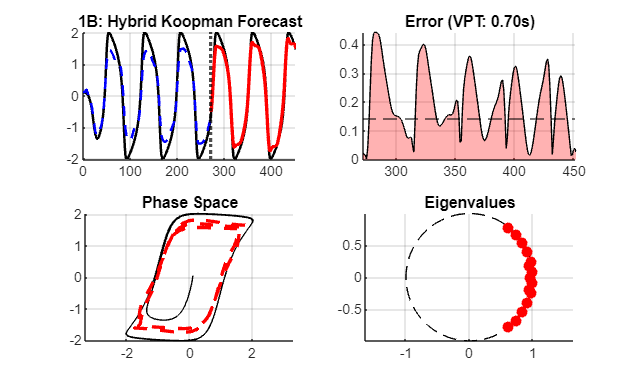


% 6. DASHBOARD
figure('Name', 'Dashboard 1B', 'Color', 'w', 'Position', [150, 50, 1000, 600]);
subplot(2,2,1); hold on; plot(1:K, H(1,:), 'k-', 'LineWidth', 1.5); 
plot(1:train_cols, signal_forecast(1:train_cols), 'b--', 'LineWidth', 1.5);
plot(train_cols+1:K, predicted, 'r-', 'LineWidth', 2); xline(train_cols, 'k:', 'LineWidth', 2);
title('1B: Hybrid Koopman Forecast'); grid on;

subplot(2,2,2); hold on; area(train_cols+1:K, err_vec, 'FaceColor', 'r', 'FaceAlpha', 0.3);
yline(thresh, 'k--'); title(['Error (VPT: ', vpt, ')']); grid on;

subplot(2,2,3); hold on; d=8; plot(H(1,1:end-d), H(1,1+d:end), 'k-');
plot(signal_forecast(train_cols+1:end-d), signal_forecast(train_cols+1+d:end), 'r--', 'LineWidth', 2);
title('Phase Space'); grid on; axis equal;

subplot(2,2,4); hold on; th=linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerFaceColor', 'r'); title('Eigenvalues'); grid on; axis equal;